# 1. Reconstruct "microangiogram" from RBC data.

Dock figure(1) and use [this layout](https://docs.google.com/document/d/1RuEO2t5K-t82QPUK-sShLjorJyRC5uLGxchojfOiYDs/edit#heading=h.3m49wo5vra7y). 

If you want to load a previously-saved analysis, skip to Section 19.

## 10. Initiate.

Select a dataset to reconstruct. You can ignore a warning message (orange color) here. The values in the instruction below are default values. 

- aid : Analysis ID (processed data will be saved by this file name)

- IX = 1, IY = 1, IZ = 1 : Mosaic numbers in Y and Z (not used yet)

comInit;

aid = 'AD6-1';  % Analysis ID

uid = 'kwalek';  % User ID
eid = '170914_AD6' ;  % Experiment ID
did = 'AD6_wk10_angio';  % Data ID
IX = 1;  IY = 1;  IZ = 1;

pathraw = ['R:/ENG_Lee-Lab_Shared/group/data/16ThorlabsSD/' uid '/' eid];  % path of rawdata
pathdata = ['D:/' uid '/' eid];  % path to save reconstructed data
if isempty(dir(pathdata))
    mkdir(pathdata);
end
% dir([pathdata '/*.mat'])
conf = ReadConf_16ThorlabsSD([pathraw '/' did '_.xml']);

## 11. Load the first volume. [0.5 hr]

SECTION 11 RUNNING ...
Starting parallel pool (parpool) using the 'local' profile ...
connected to 2 workers.
15:55 motion correction... 500/2048
15:56 motion correction... 1000/2048


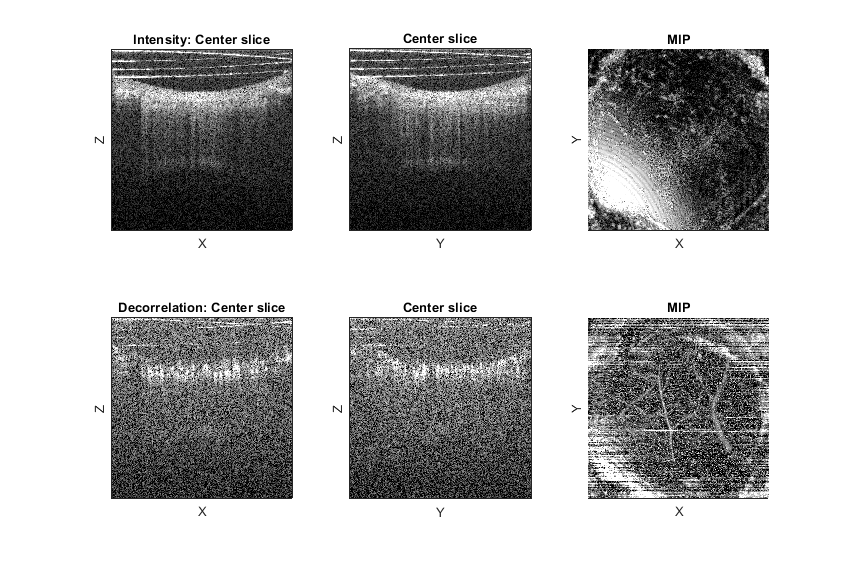

SECTION 11 COMPLETED.


sec11;

## 12. Exclude glass images and other artifacts.

Please move up/down and rotate a plane, over which the images will be considered as artifacts and removed.

Parameters:

- dzc = 5 : Pixel numbers to move by E/D keys

- da = 0.01 : Angle (slope) to rotate by S/F/W/R keys

- ned = 100 : Pixel position from the edge to monitor the red plane

UI keys:

- Q: Quit

- G: Click four points: two points under the bottom glass artifact in X-Z plane and the same in Y-Z plane.

- E/D: Move the center of the plane 

- S/F: Rotate the plane along Y axis (in X-Z plane)

- W/R: Rotate the plane along X axis (in Y-Z plane)

SECTION 12 RUNNING ...


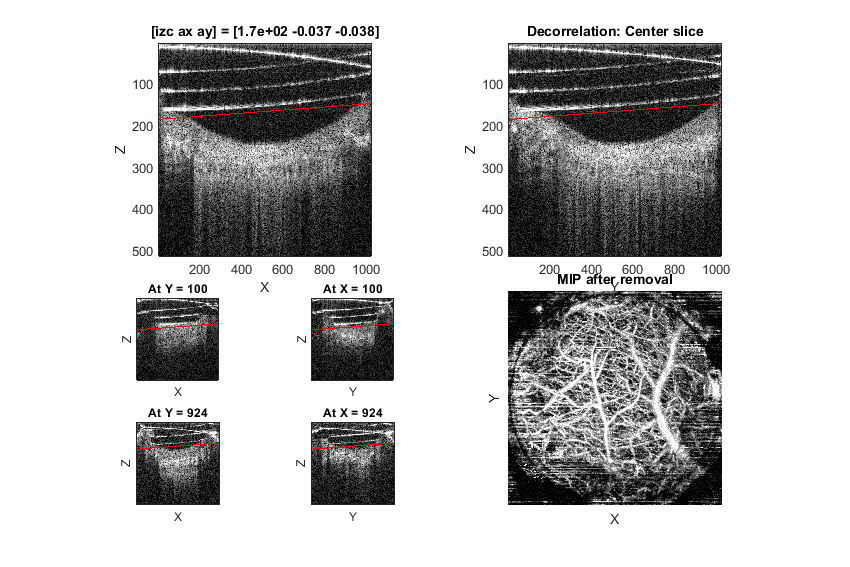

SECTION 12 COMPLETED.


dzc = 5;
da = 0.01;
ned = 100;

sec12;

**Check points:**

- Do your red plane position well in the four small figures as well?

- Did large-area artifacts disappear from the MIP?

## 13. Determine the optimal *dk* value.

If you want to find the optimal value for this dataset, set *dk* = 0 and run section. If you already know what is optimal and want to use it, set the non-zero value below and run this section.

- dk = 0 : If you already know the optimal value and want to skip this section, set the value and run this section.

- dkr = 0.23+(-4:4)*0.01 : The range of dk to test. If this section cannot find the optimal, try different ranges.

SECTION 13 RUNNING ...


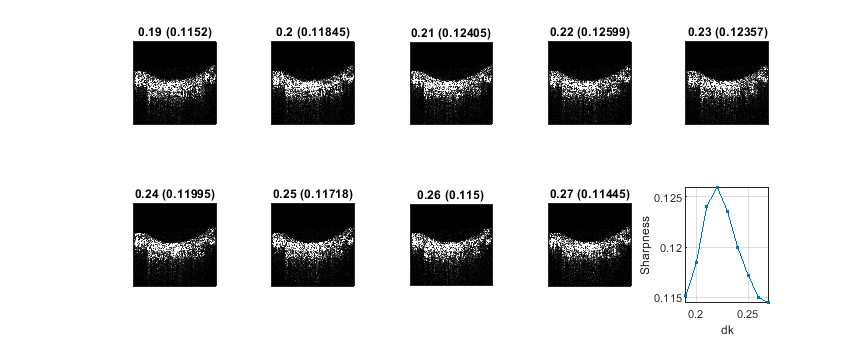

dk = 0.2200

SECTION 13 COMPLETED.


dk = 0;  % find a new value only when this is set to zero.
dkr = 0.23+(-4:4)*0.01;

if dk == 0
    sec13;
end

**Check points:**

- Is your sharpness curve concave with a clear maximum?

## 14. Determine the bottom depth to crop.

Parameters

- DR = 10 : Dynamic range for the initial guess (nz1 s.t. Dz(nz1) = max(Dz)/DR)

- dz = 20 : Pixel number to move the depth

UI keys

- Q: Quit

- G: Select the bottom depth manually.

- S/F: Move the bottom depth 

SECTION 14 RUNNING ...


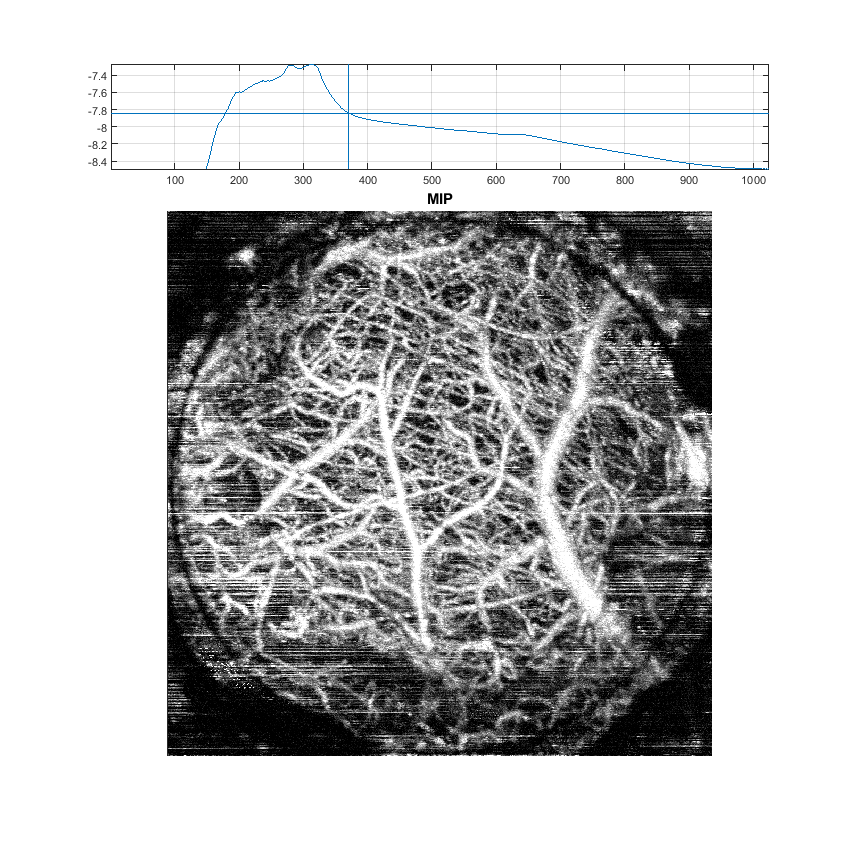

SECTION 14 COMPLETED.


DR = 10;
dz = 20;

sec14;

## 15. Load all volumes and conduct the automatic contrast-masked averaging.


sec15;

## 11. Determine the optimal *dk *value.

If you want to find the optimal value for this dataset, set *dk* = 0 and run section. If you already know what is optimal and want to use it, set the non-zero value below and run section.

dk = 0;  % find a new value only when this is set to zero.

if dk == 0
    sec11;
end

## 12. Contrast-masked averaging (automatic)